# MHKiT Strain Measurement Example

## Introduction

This example demonstrates how to process experimental strain data and calculate forces. This notebook is based on the laboratory testing of a tidal turbine blade [1]. This MATLAB example was first developed in MHKiT-Python [2] and converted to MATLAB. In the experimental campaign, the turbine blade is mounted to a vertical wall and a known load is applied near the blade tip causing shear forces, bending moments, and torsion at the blade root. Note that the horizontal profiles of shear and bending moment, below, are simplified illustrations for the case of a uniform, cantilevered beam.

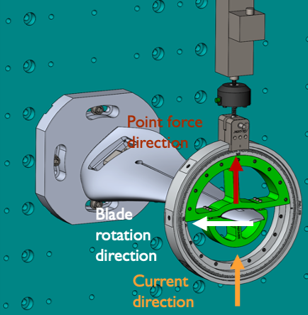

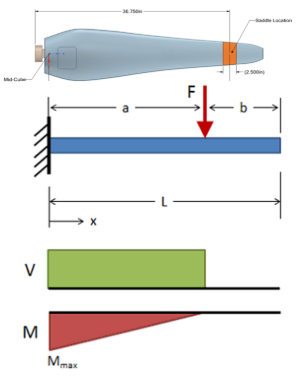

The blade root (below) inserts inside the blade and mounts the blade to the hub. This interface contains a thin-walled, cuboid section with circular hole through the center for cable routing.

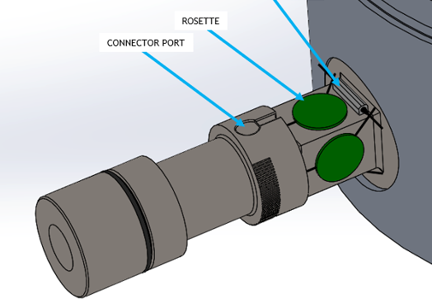

Four, 90 degree strain rosettes (top, bottom, left, right) are mounted to the outer flat surfaces of the thin-walled cuboid. Each strain rosette has a local coordinate system, denoted in the figure below. The global coordinate system corresponds to the blade orientation. The strain gauges are calibrated using the known load and measured strain at the blade root.

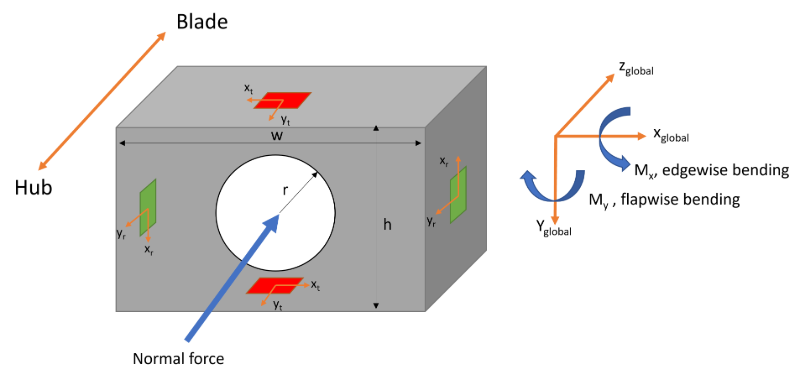

Due to the highly variable nature of experimental configurations, these functions are not included in an MHKiT module. This example can be used as a guide to process strain data from other experimental configurations.

## Loading and Organizing Original Data

First we will load strain data and map rosettes to TBLR (top, bottom, left, right). The strain data is contained in a CSV file `./examples/data/strain/R17.csv`. Time is the first column. Strain data is ordered by rosette and each rosette corresponds to three strain measurements (ea, eb, ec). Rosettes 1, 2, 3, 4 correspond to the top, bottom, left, and right rosettes in the global coordinate system.

% Original csv has no header
raw_data = readtable('data/strain/R17.csv', 'ReadVariableNames', false);

% Rename the variable names (column names)
raw_data.Properties.VariableNames = {'time', ...
    'ea_1', 'eb_1', 'ec_1', ...
    'ea_2', 'eb_2', 'ec_2', ...
    'ea_3', 'eb_3', 'ec_3', ...
    'ea_4', 'eb_4', 'ec_4'};

time = raw_data.time;

## Visualize Original Measurement

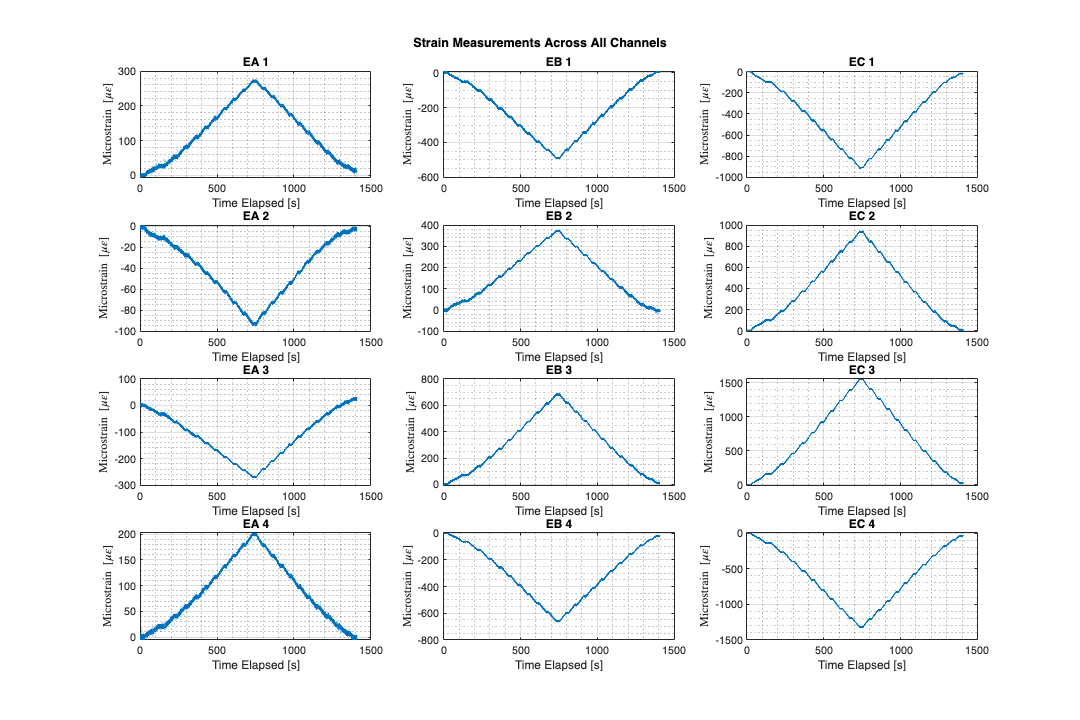

% Create figure
figure('Position', [100, 100, 1200, 800])

% Number of channels (excluding time)
num_channels = size(raw_data, 2) - 1;

% Create subplot for each channel
for i = 1:num_channels
    subplot(4, 3, i)

    % Get channel name and data
    channel_name = raw_data.Properties.VariableNames{i+1};
    channel_data = raw_data{:, i+1};

    % Create plot
    plot(time, channel_data, 'LineWidth', 1.5)

    % Add grid
    grid on

    % Add labels
    xlabel('Time Elapsed [s]')
    ylabel('$\mathrm{Microstrain}\ [\mu\varepsilon]$', 'Interpreter', 'latex')

    % Add title (format the channel name for better readability)
    channel_name = strrep(channel_name, '_', ' ');
    title(upper(channel_name), 'FontWeight', 'bold')

    % Customize appearance
    set(gca, 'FontSize', 12)
    set(gca, 'Box', 'on')

    % Add minor grid lines
    grid minor
end

% Adjust spacing between subplots
sgtitle('Strain Measurements Across All Channels', 'FontSize', 14, 'FontWeight', 'bold')

## Initialize Data Structures

Organize strain data into matrices for easier handling

ea = [raw_data.ea_1, raw_data.ea_2, raw_data.ea_3, raw_data.ea_4];  % ea_1 through ea_4
eb = [raw_data.eb_1, raw_data.eb_2, raw_data.eb_3, raw_data.eb_4];  % eb_1 through eb_4
ec = [raw_data.ec_1, raw_data.ec_2, raw_data.ec_3, raw_data.ec_4];  % ec_1 through ec_4

% Create a structure to store all data
data = struct();
data.time = time;
data.rosette = 1:4;
data.rosetteName = {'top', 'bottom', 'left', 'right'};

## Conversion From Microstrain, $\mu \epsilon$ to Strain, $\epsilon$,

microstrain_to_strain_scaling_factor = 1e-6;

% Add microstrain to data struct
data.ea = ea * microstrain_to_strain_scaling_factor;
data.eb = eb * microstrain_to_strain_scaling_factor;
data.ec = ec * microstrain_to_strain_scaling_factor;

Define the geometry of the cuboid in the blade root where strain gauges are attached.

width = 44.6024 / 1000;     % width of cuboid [m]
height = 44.6024 / 1000;    % height of cuboid [m]
radius = 15.24 / 1000;      % radius of hole in the cuboid [m]
blade_span = 0.86868;       % Span from strain rosettes to point of blade loading [m]

Define material properties of the cuboid

elastic_modulus = 197e9;    % [Pa]
shear_modulus = 77.4e9;     % [Pa]

## Calculating Axial and Shear Strain

## 90 Degree Rosettes

We now have all strain data contained in a struct with fieldnames corresponding to measured strain. The local y-axis of each rosette corresponds to the global z-axis. Each rosette is locally oriented like the following coordinate system.

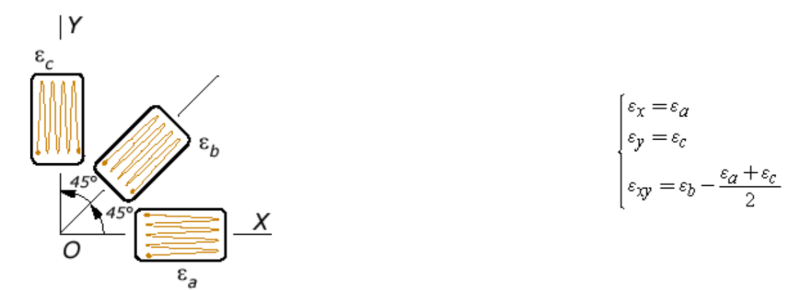

Now we can calculate the axial strains and shear strain for each 90 degree rosette.

data.axial_strain_x = data.ea;
data.axial_strain_y = data.ec;
data.shear_strain = data.eb - (data.ea + data.ec) / 2;

## Alternate Equations for 120 Degree Rosettes

If we had 120 degree rosettes, we could calculate the axial and shear strains from the measured strains in a similar manner using the respective equations:

% data.axial_strain_x = 2 / 3 * (data.ea - data.eb / 2 + data.ec);
% data.axial_strain_y = data.eb;
% data.shear_strain = 1 / sqrt(3) * (data.ea - data.ec)

## Calculate Loads From Strain

## Define Equations for Normal Force, Moment, and Torsion

Because the strain is measured on a rectangular prism, the normal force, moment and torsion use similar equations. We first create three functions that calculate the normal force, moment, and torsion given some strain and geometrical inputs. The torsion is calculated for each rosette. The normal force and moment are calculated using rosette pairs to eliminate the effect of the bending moment on axial strain when calculating the normal force, and vice versa.

% Define helper functions
function normal = calculate_normal(axial_strain_1, axial_strain_2, elastic_modulus, shear_modulus, width, height, radius)
    normal = 0.5 * (axial_strain_1 + axial_strain_2) * elastic_modulus * ...
        (width * height - pi * radius^2);
end

function moment = calculate_moment(axial_strain_1, axial_strain_2, elastic_modulus, shear_modulus, width, height, radius)
    moment = (axial_strain_1 - axial_strain_2) / height * elastic_modulus * ...
        (width * height^3 / 12 - pi * radius^4 / 4);
end

function torsion = calculate_torsion(shear_strain, shear_modulus, width, height, radius)
    polar_moment_of_inertia = (width^3 * height + width * height^3) / 12 - ...
        pi * radius^4 / 2;
    torsion = shear_strain * shear_modulus * polar_moment_of_inertia / (height / 2);
end

## Calculate Normal Force and Bending Moments

We will use the three custom functions to calculate the normal force and bending moments with the top and bottom rosette pair, and then based on the left and right rosette pair.

% Top and bottom rosettes
data.normal_topBottom = calculate_normal(data.axial_strain_y(:,1), ...
    data.axial_strain_y(:,2), elastic_modulus, shear_modulus, width, height, radius);

data.moment_x = calculate_moment(data.axial_strain_y(:,1), ...
    data.axial_strain_y(:,2), elastic_modulus, shear_modulus, width, height, radius);

% Right and left rosettes
% Note: height and width inputs are switched due to the different orientation
data.normal_leftRight = calculate_normal(data.axial_strain_y(:,3), ...
    data.axial_strain_y(:,4), elastic_modulus, shear_modulus, height, width, radius);

data.moment_y = calculate_moment(data.axial_strain_y(:,3), ...
    data.axial_strain_y(:,4), elastic_modulus, shear_modulus, height, width, radius);

## Calculate Torsion

Next we will calculate the torsion using the shear strain of each rosette and find the average torsion load.

% Calculate torsion for each rosette
data.torsion_top = calculate_torsion(data.shear_strain(:,1), shear_modulus, width, height, radius);
data.torsion_bottom = calculate_torsion(data.shear_strain(:,2), shear_modulus, width, height, radius);

% Note: height and width inputs are switched due to the different orientation
data.torsion_left = calculate_torsion(data.shear_strain(:,3), shear_modulus, height, width, radius);
data.torsion_right = calculate_torsion(data.shear_strain(:,4), shear_modulus, height, width, radius);

% Calculate mean torsion
data.torsion_mean = (data.torsion_top + data.torsion_bottom + ...
    data.torsion_right + data.torsion_left) / 4;

## Rotate Loads to Blade Coordinate System

It is possible that the blade coordinate system is not aligned to the global coordinate system. This could be due to limitations of the experimental configuration or intentional to enable the use of strain gauges with larger loads.

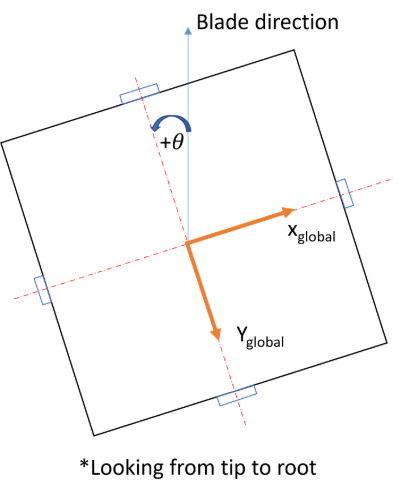

In this case, we can transform the bending moment from the global coordinate system to align with the blade's flapwise direction.

% Calculate rotated moments
angle = 0 * pi / 180;  % rotation angle of the root
data.moment_flapwise = data.moment_x * cos(angle) - data.moment_y * sin(angle);
data.moment_edgewise = data.moment_x * sin(angle) + data.moment_y * cos(angle);

## Visualize Loads

We can now plot various quantities of interest, including the normal force at the blade root, flapwise and edgewise bending moments, equivalent load applied to the blade, and torsion. These quantities are then used to validate the experimental set-up using the known loads before advancing to an open-water test campaign.

## Normal Forces

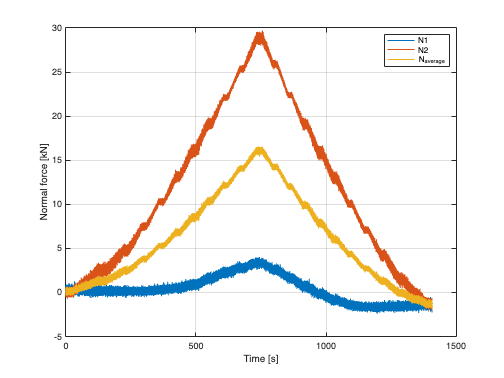

figure;
plot(data.time, data.normal_topBottom/1000, ...
     data.time, data.normal_leftRight/1000, ...
     data.time, (data.normal_topBottom + data.normal_leftRight)/2000);
legend('N1', 'N2', 'N_{average}', 'Location', 'best');
ylabel('Normal force [kN]');
xlabel('Time [s]');
grid on;

## Moments

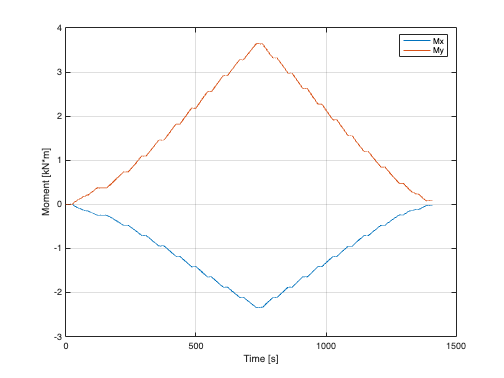

figure;
plot(data.time, data.moment_x/1000, ...
     data.time, data.moment_y/1000);
legend('Mx', 'My', 'Location', 'best');
ylabel('Moment [kN*m]');
xlabel('Time [s]');
grid on;

## Blade Load

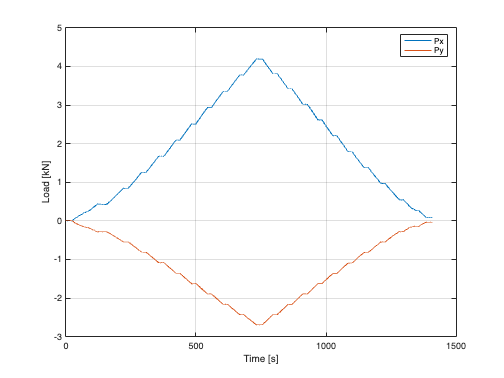

figure;
plot(data.time, data.moment_y/(blade_span * 1000), ...
     data.time, data.moment_x/(blade_span * 1000));
legend('Px', 'Py', 'Location', 'best');
ylabel('Load [kN]');
xlabel('Time [s]');
grid on;

## Torsion

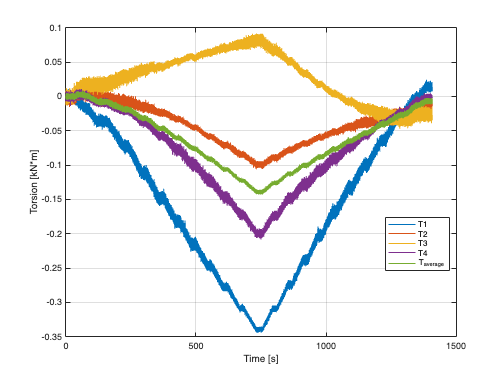

figure;
plot(data.time, data.torsion_top/1000, ...
     data.time, data.torsion_bottom/1000, ...
     data.time, data.torsion_left/1000, ...
     data.time, data.torsion_right/1000, ...
     data.time, data.torsion_mean/1000);
legend('T1', 'T2', 'T3', 'T4', 'T_{average}', 'Location', 'best');
ylabel('Torsion [kN*m]');
xlabel('Time [s]');
grid on;

## References

[1] Gunawan, Budi, et al. "Calibration Of Fiber Optic Rosette Sensors For Measuring Bending Moment On Tidal Turbine Blades." International Conference on Ocean Energy, Melbourne, Australia, September 17 – 19, 2024.

[2] Keester, Adam. "Strain Measurement Example." MHKiT-Python, GitHub Repository (ca9709f), July 17, 2024. [https://github.com/MHKiT-Software/MHKiT-Python/commit/ca9709f1df066b32305ebf85acae3886b15003bd](https://github.com/MHKiT-Software/MHKiT-Python/commit/ca9709f1df066b32305ebf85acae3886b15003bd)